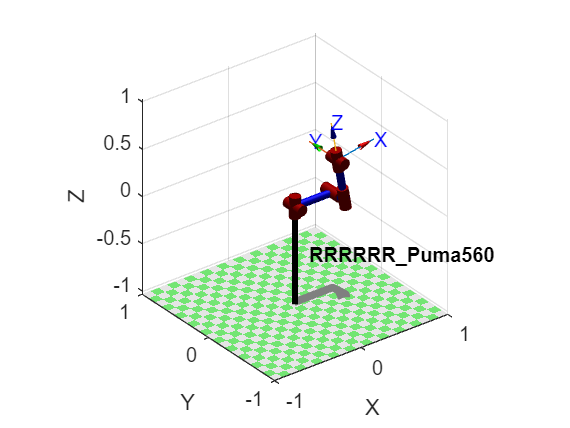

clc
clear
close all

% Puma560机器人
% theta         d               a               alpha
theta1 = 0.0;   d1 = 0.0;       a1 = 0.0;       alpha1 = pi/2;
theta2 = 0.0;   d2 = 0.0;       a2 = 0.4318;    alpha2 = 0;
theta3 = 0.0;   d3 = 0.15005;   a3 =  0.0203;   alpha3 = -pi/2;
theta4 = 0.0;   d4 = 0.4318;    a4 = 0.0;       alpha4 = pi/2;
theta5 = 0.0;   d5 = 0.0;       a5 = 0.0;       alpha5 = -pi/2;
theta6 = 0.0;   d6 = 0.0;       a6 = 0.0;       alpha6 = 0;

Lr1 = Link('revolute', 'd', d1, 'a', a1, 'alpha', alpha1, 'qlim',[-pi,pi]);
Lr2 = Link('revolute', 'd', d2, 'a', a2, 'alpha', alpha2, 'qlim',[-pi,pi]);
Lr3 = Link('revolute', 'd', d3, 'a', a3, 'alpha', alpha3, 'qlim',[-pi,pi]);
Lr4 = Link('revolute', 'd', d4, 'a', a4, 'alpha', alpha4, 'qlim',[-pi,pi]);
Lr5 = Link('revolute', 'd', d5, 'a', a5, 'alpha', alpha5, 'qlim',[-pi,pi]);
Lr6 = Link('revolute', 'd', d6, 'a', a6, 'alpha', alpha6, 'qlim',[-pi,pi]);
robot = SerialLink([Lr1 Lr2 Lr3 Lr4 Lr5 Lr6], 'name', 'RRRRRR\_Puma560');

% 指定关节变量
q1 = 0; q1 = q1*pi/180;     % 第一个关节的回转角度
q2 = 0; q2 = q2*pi/180;     % 第二个关节的回转角度
q3 = 10; q3 = q3*pi/180;     % 第三个关节的伸缩长度
q4 = 0; q4 = q4*pi/180;     % 第一个关节的回转角度
q5 = 0; q5 = q5*pi/180;     % 第二个关节的回转角度
q6 = 0; q6 = q6*pi/180;     % 第一个关节的回转角度
q = [q1, q2, q3, q4, q5, q6];
robot.plot(q);

syms theta1 theta2
l1 = 0.5

l1 = 0.5000

l2 = 0.5

l2 = 0.5000

x = l1*cos(theta1)+l2*cos(theta1+theta2)

$$x = \frac{\cos\left(\theta_{1}+\theta_{2}\right)}{2}+\frac{\cos\left(\theta_{1}\right)}{2}$$

y = l1*sin(theta1)+l2*sin(theta1+theta2)

$$y = \frac{\sin\left(\theta_{1}+\theta_{2}\right)}{2}+\frac{\sin\left(\theta_{1}\right)}{2}$$

J = jacobian([x,y],[theta1,theta2])

$$J = \left(\begin{array}{cc} -\frac{\sin\left(\theta_{1}+\theta_{2}\right)}{2}-\frac{\sin\left(\theta_{1}\right)}{2} & -\frac{\sin\left(\theta_{1}+\theta_{2}\right)}{2}\\ \frac{\cos\left(\theta_{1}+\theta_{2}\right)}{2}+\frac{\cos\left(\theta_{1}\right)}{2} & \frac{\cos\left(\theta_{1}+\theta_{2}\right)}{2} \end{array}\right)$$

matrix1 = subs(J,{theta1,theta2},{0,0})

$$matrix1 = \left(\begin{array}{cc} 0 & 0\\ 1 & \frac{1}{2} \end{array}\right)$$

det(matrix1)

$$ans = 0$$

matrix2 =subs(J,{theta1,theta2},{0,pi/2})

$$matrix2 = \left(\begin{array}{cc} -\frac{1}{2} & -\frac{1}{2}\\ \frac{1}{2} & 0 \end{array}\right)$$

det(matrix2)

$$ans = \frac{1}{4}$$

matrix3 =subs(J,{theta1,theta2},{pi/2,0})

$$matrix3 = \left(\begin{array}{cc} -1 & -\frac{1}{2}\\ 0 & 0 \end{array}\right)$$

det(matrix3)

$$ans = 0$$

matrix4 =subs(J,{theta1,theta2},{pi/4,0.8*pi})

$$matrix4 = \left(\begin{array}{cc} \frac{\sin\left(\frac{\pi }{20}\right)}{2}-\frac{\sqrt{2}}{4} & \frac{\sin\left(\frac{\pi }{20}\right)}{2}\\ \frac{\sqrt{2}}{4}-\frac{\cos\left(\frac{\pi }{20}\right)}{2} & -\frac{\cos\left(\frac{\pi }{20}\right)}{2} \end{array}\right)$$

det(matrix4)

$$ans = \frac{\sqrt{2}\,\cos\left(\frac{\pi }{20}\right)}{8}-\frac{\sqrt{2}\,\sin\left(\frac{\pi }{20}\right)}{8}$$